## Spring Mass Damper Model (2DOF) for predicting fuel slosh in a launch vehicle under high accelaration regimes

This code simulates lateral slosh in a high-G regime. Typically, high-G slosh is modelled with mechanical analogue models of a spring-mass model. The Equations of motion come from ["Development and validation of a simple two degree of freedom model for predicting maximum fundamental sloshing mode wave height in a cylindrical tank" by Sharma et al](https://www.sciencedirect.com/science/article/abs/pii/S0022460X19304687?via%3Dihub).

1 DOF model was inititally formulated by Abramson et al., in ["Representation of Fuel Sloshing in Cylindrical Tanks by an Equivalent Mechanical Model"](https://arc.aiaa.org/doi/10.2514/8.5896)

clear;close all;clc
cd("C:\Users\trameshk\OneDrive - MathWorks\Documents\Tech-projects\Project - Fuel sloshing in High g manuevers\Fuel_sloshing_simulink_model\fuel_slosh_practice")

### Step 1: Open Model

mdl = 'slosh_simulink_SpringMassDamper';
open_system(mdl)

### Step 2: Set Model Parameters

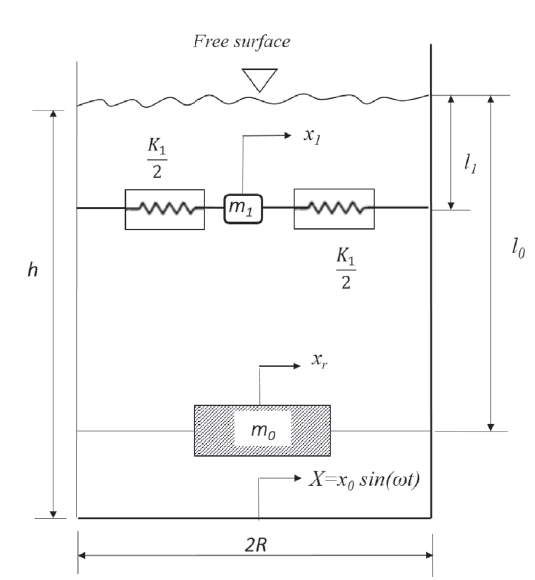

For a circular cylindrical tank with flat bottom, the damping ratio can be estimated empirically as [2],


$$\zeta_1 = 4.98\nu^{1∕2}R^{-3/4}g^{-1/4}$$


Stiffness of fundamental modal mass can be obtained from,


$$\frac{K_1}{M} = \frac{g\tanh{\big(1.84\frac{h}{R}\big)^2}}{1.19h}

$$


g                        = 9.81; % Accelaration due to gravity
R                        = 200*10^-3; % Radius of tank (m)
mVehicle                 = [39.27 51.37 63.86 76.41]; % Mass of tank + non-sloshing liquid (kg)
mSlosh                   = [10.86 11.33 11.41 11.42]; % Sloshing mass (kg)
mFuel                    = mVehicle+mSlosh; % Total liquid mass (kg)
hFuel                    = [0 0.2 0.3 0.4 0.5]';
fResonance               = [1.47 1.51 1.51 1.51]; % Resonant frequency
fPreRes                  = 1.3; 
fPostRes                 = 1.6; % pre and post resonant frequency for testing
fVehicle                 = [297.8 277.9 250.7 225.3]; 
zetaVehicle              = 0.0015    % empirically calculated

zetaVehicle = 0.0015

KVehicle                 = mVehicle.*(2.*pi.*fVehicle).^2;
% CVehicle                 = zetaVehicle*2*sqrt(mVehicle.*KVehicle)
% KSlosh                   = mFuel*g.*tanh((1.84.*hFuel/R).^2)./(1.19.*hFuel);
% viscosityFuel            = 1.05e-6;
% xiSlosh                  = 4.98*sqrt(viscosityFuel)*R^(-3/4)*g^(-1/4)
% CSlosh                   = xiSlosh*2*sqrt(mSlosh'.*KSlosh)
C_0                      = [228.48 273.56 362.38 382.73]; % Damping coefficient of m_0  (Ns/m)
C_1                      = [0.52 0.55 0.56 0.56]; % Damping coefficient of m_1 (Ns/m)
KVehicle                 = [1.62e8 1.79e8 1.77e8 1.68e8]; % Stiffness coefficient of m_0  (N/m)
K_1                      = [936.5 1019.47 1033.30 1035.51]; % Stiffness coefficient of m_1 (N/m)
massMatrix               = zeros(2,2,length(mVehicle));
dampingCoeffMatrix       = zeros(2,2,length(mVehicle));
stiffnessCoeffMatrix     = zeros(2,2,length(mVehicle));
for i = 1:length(mVehicle)
    massMatrix(:,:,i)           = [mVehicle(i) 1;1 mSlosh(i)];
    dampingCoeffMatrix(:,:,i)   = [C_0(i)+C_1(i) -C_1(i);-C_1(i) C_1(i)];
    stiffnessCoeffMatrix(:,:,i) = [(KVehicle(i)+K_1(i)) -K_1(i); -K_1(i) K_1(i)];
end
